data = readtable('cptitanium.xlsx');
data.Properties.VariableNames = {'Strain','Strain Rate','T1','T2','T3','T4','T5','T6'}

data = 31x8 table
    Strain    Strain Rate     T1       T2       T3       T4       T5       T6 
    ______    ___________    _____    _____    _____    _____    _____    ____

     NaN           NaN         300      400      450      500      600     700
     0.1         0.001        64.1     51.9       41     31.3     24.6    18.5
     0.1          0.01        86.8     67.3     54.2     43.1     34.7    26.6
     0.1           0.1        99.7     87.8     65.6     55.7     44.3    37.9
     0.1             1         120    102.1     85.6     74.3     60.7    51.3
     0.1            10       137.2    106.2     97.6       94     80.8    67.9
     0.1           100         130    115.7      108    106.3       95      8

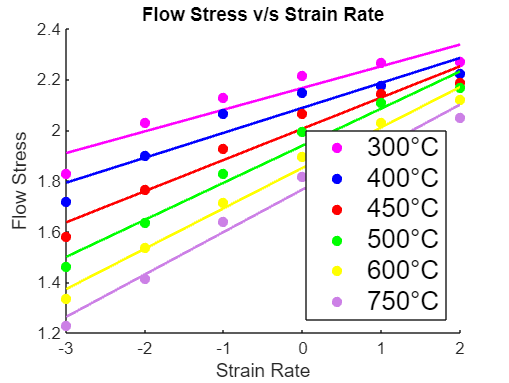

data(1,:)=[];


datan= table2array(data);
% 0.1 strain
strain_1 = datan(13:18,2:end);
sr1 = strain_1(:,1);
strainlog = log10(sr1);
stress1 = strain_1(:,2:end);y = zeros(6,6);
stresslog = log10(stress1);
C = {'m','b','r','g','y',[.8 .5 .9]};
hold on
for r = 1:length(stress1)
    Scatter(r) =scatter(strainlog,stresslog(:,r),'filled','MarkerFaceColor',C{r});
    c= polyfit(log10(sr1),log10(stress1(:,r)),1);
    y(:,r) = polyval(c,log10(sr1));
    plot(log10(sr1),y(:,r),'LineWidth',1.5,'Color',C{r})
end
ylabel('Flow Stress');xlabel('Strain Rate');
title('Flow Stress v/s Strain Rate')
legend(Scatter,'300°C','400°C','450°C','500°C','600°C','750°C','Location','southeast','FontSize',15);
hold off



%slope or strain rate sensitivity
%slope or strain rate sensitivity
m= zeros(length(stress1),length(stress1));
for k =  1:length(stress1)
    for p = 1:length(stress1)
        c1= polyfit(log10(sr1),log10(stress1(:,k)),3);
        deriv = polyder(c1);
        m(p,k) = polyval(deriv,strainlog(p));
    end
end



e= (2*m./(m+1))*100;
T= 300:50:550;
%instability zone
e1= e/200;
slope= zeros(length(stress1),length(stress1));
for k =  1:length(stress1)
    for p =  1:length(stress1)
        c2= polyfit(log10(sr1),log10(e1(:,k)),3);
        deriv = polyder(c2);
        slope(p,k) = polyval(deriv,strainlog(p));
        
    end
end
iz = slope +m;

## Fit: 'untitled fit 1'.

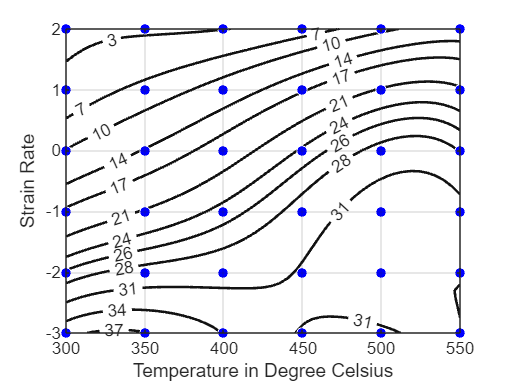

[xData, yData, zData] = prepareSurfaceData( T, strainlog, e );

% Set up fittype and options.
ft = fittype( 'poly45' );

% Fit model to data.
[fitresult, gof] = fit( [xData, yData], zData, ft, 'Normalize', 'on' );

% Make contour plot.
figure( 'Name', 'Power Dissipation' );
h = plot( fitresult, [xData, yData], zData, 'Style', 'Contour' );
% Label axes
xlabel( 'Temperature in Degree Celsius', 'Interpreter', 'none' );
ylabel( 'Strain Rate', 'Interpreter', 'none' );

grid on
set(h(1),'ShowText','on','LabelSpacing',144)
set(h(1),'LineWidth',1.5,'Fill','off');
set(h(1),'LevelList',[3,7,10,14,17,21,24,26,28,31,34,37,41,45,48,52])
fig = gcf;
saveas(gcf,'pd0_5.jpg')

## Fit: 'untitled fit 2'.

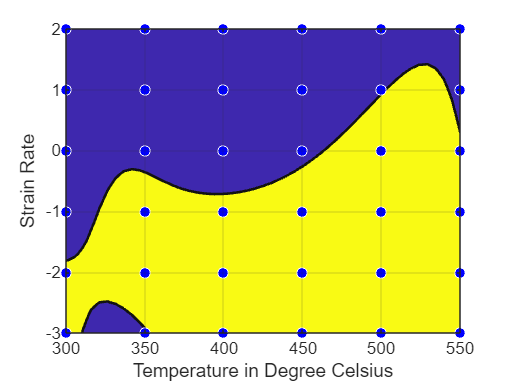

[xData, yData, zData] = prepareSurfaceData( T, strainlog, iz );

% Set up fittype and options.
ft = fittype( 'poly45' );

% Fit model to data.
[fitresult, gof] = fit( [xData, yData], zData, ft, 'Normalize', 'on' );

% Make contour plot.
figure( 'Name', 'untitled fit 2' );
w=plot( fitresult, [xData, yData], zData, 'Style', 'Contour' );
% Label axes
xlabel( 'Temperature in Degree Celsius', 'Interpreter', 'none' );
ylabel( 'Strain Rate', 'Interpreter', 'none' );
grid on
set(w(1),'LineWidth',1.5);
set(w(1),'LineWidth',1.5,'LevelStep',2);
fig = gcf;
saveas(gcf,'is0_5.jpg')

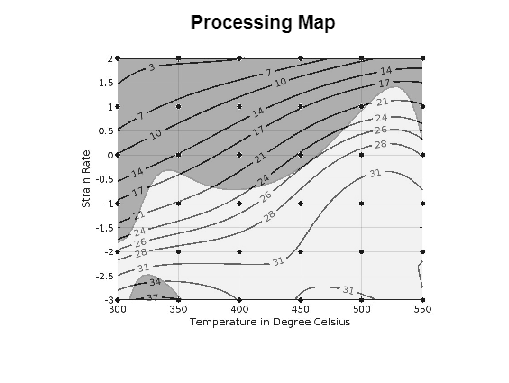



% BASIC IMAGE PROCESSING : SUPERIMPOSE
fig1 = imread('pd0_5.jpg');
fig2 = imread('is0_5.jpg');
fusionimage=imfuse(fig1,fig2,'falsecolor','Scaling','joint');
op=rgb2gray(fusionimage);
imshow(op);
title('Processing Map')